**QPSK :**

Step 1: Declare the number of binary data bits and generate them randomly.

z=10^5 ;
%%z=size of data 
b=randi(2,z,1) ;
c=randi(2,z,1) ;
%%binary data
dataX=b-1 ;
dataY=c-1 ;
for a=1:z
    Qdata(a,1)=dataX(a) ;
    Qdata(a,2)=dataY(a) ;
end
disp('Binary Data containing two bits at a time :') ;

Binary Data containing two bits at a time :


Qdata

Qdata =      1     0
     1     1
     1     0
     1     0
     1     0
     1     1
     0     0
     1     0
     1     0
     1     1


Step 2: Perform bit to symbol mapping - BPSK modulation

%%symbol sequence
Qsdata=Qdata ;
for i=1:z
    if Qsdata(i,1)==0 && Qsdata(i,2)==0 
        Qsdata(i,1)=-1 ;Qsdata(i,2)=-1 ;
    elseif Qsdata(i,1)==0 && Qsdata(i,2)==1 
        Qsdata(i,1)=-1 ;
    elseif Qsdata(i,1)==1 && Qsdata(i,2)==0 
        Qsdata(i,2)=-1 ;
    end
end
disp('Binary Data mapped to symbols :') ;

Binary Data mapped to symbols :


Qsdata

Qsdata =      1    -1
     1     1
     1    -1
     1    -1
     1    -1
     1     1
    -1    -1
     1    -1
     1    -1
     1     1


Step 3: Generate AWGN noise of a certain SNR value and add to the BPSK modulated bits

%%dBN=SNR value in dB.
%%Limit of SNR.
s=10 ;
%%error=array to store errors at each SNR.
bitError=zeros(1,s) ;
for dBN=1:1:s
    var = 1/(10^(0.1*(dBN-1))) ;
    noiseX = sqrt(var/2).*randn(z,1) ;
    noiseY = sqrt(var/2).*randn(z,1) ;
    i=1:z ; 
    y= Qsdata ;
    y(i,1) =Qsdata(i,1)+noiseX(i) ;
    y(i,2) =Qsdata(i,2)+noiseY(i) ;
    scatter(y(i,1),y(i,2)) ;

Step 4: Demodulate using ML detection

    Qmest=zeros(z,2) ;
    for j=1:z    
        if y(j,1)>0 && y(j,2)>0
            Qmest(j,1)=1 ; Qmest(j,2)=1 ;
        elseif y(j,1)<0 && y(j,2)>0
            Qmest(j,1)=-1 ;Qmest(j,2)=1 ;
        elseif y(j,1)<0 && y(j,2)<0
            Qmest(j,1)=-1 ;Qmest(j,2)=-1 ;
        else 
            Qmest(j,1)=1 ;Qmest(j,2)=-1 ;
        end
    end

Step 5: Map the demodulated symbols to bits

    m=Qmest ;
    for k=1:z    
        if Qmest(k,1)==-1 && Qmest(k,2)==-1
            m(k,1)=0 ; m(k,2)=0 ;
        elseif Qmest(k,1)==-1 && Qmest(k,2)==1
            m(k,1)=0 ;
        elseif Qmest(k,1)==1 && Qmest(k,2)==-1
            m(k,2)=0 ;
        end
    end
   

Step 6: Compare the demodulated bits with the data bits to obtain BER

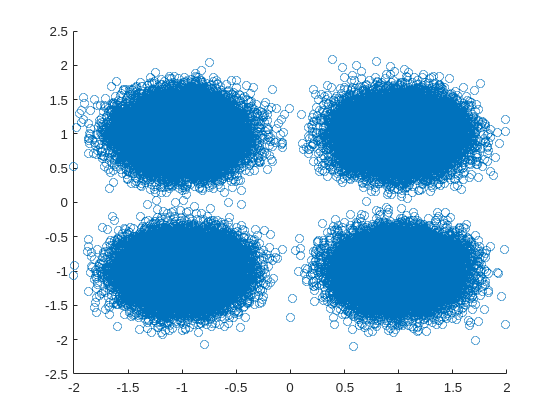

    for l=1:z 
        if m(l,1)~=Qdata(l,1) && m(l,2)~=Qdata(l,2)
            bitError(dBN)=bitError(dBN)+2 ;
        elseif m(l,1)~=Qdata(l,1) && m(l,2)==Qdata(l,2)
            bitError(dBN)=bitError(dBN)+1 ;
        elseif m(l,1)==Qdata(l,1) && m(l,2)~=Qdata(l,2)
            bitError(dBN)=bitError(dBN)+1 ;
        else 
            bitError(dBN)=bitError(dBN)+0 ;
        end
    end
end

disp('An example of noise-added signal :') ;

An example of noise-added signal :


y

y =     0.7271   -0.9405
    0.7702    0.6585
    1.2728   -0.9432
    0.5405   -0.8172
    0.8806   -1.4146
    0.8585    0.6157
   -0.8176   -0.7042
    1.0760   -0.8713
    0.8702   -0.5274
    1.1452    1.3364


bitError

bitError =        15369       11306        7549        4514        2557        1203         504         153          35           5


Step 7: Plot BER v/s SNR curve for a range of SNR values

QBER=zeros(1,s) ;
for p=1:s
    QBER(p)=bitError(p)/(2*z) ;
end
semilogy([0,1,2,3,4,5,6,7,8,9],QBER) ;
hold on ; 
grid on
xlabel("SNR(in dB)")
ylabel("BER (log-scale)")

Step 8: Obtain the theoretical BER values through Q-function and compare with the simulated values

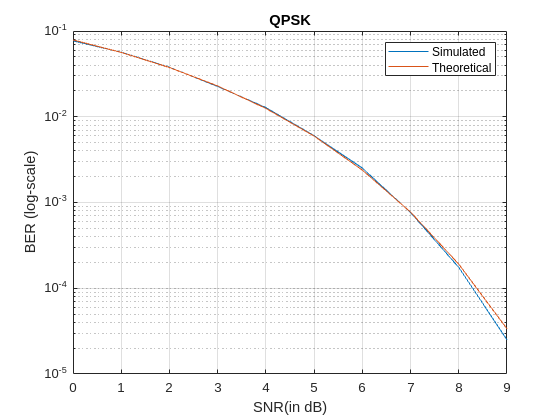

QtheoBER=zeros(size(QBER)) ;
for m=1:s
    n0=10^(-0.1*(m-1)) ;
    QtheoBER(m)= qfunc(sqrt(2/n0)) ;
end
semilogy([0,1,2,3,4,5,6,7,8,9],QtheoBER) ;
hold off ;
legend(["Simulated","Theoretical"])
title("QPSK")

Observation and Inference:

- Comment on the BER v/s SNR curve

- How will the performance differ if MAP is used instead of ML?

- Will the performance differ if the mapping of bits to symbols change? That is if bit 0 is mapped to -1 and bit 1 is mapped to +1 and vice versa?

- Comment on the theoretical and simulated BER values.